# Proyecto Final: Moviles y Gravedad

## **Algoritmos Numéricos por Computadora**

## Manuel Fernández 166496

## Bernardo Altamirano 167881

## Santiago Borobia 165323

## Introducción:

Cuando modelamos dos masas que conviven en un mismo espacio y, por lo tanto, muestran fuerzas de atracción entre ellas lo hacemos de la siguiente manera.

Primero, comencaremos con un ejemplo sencillo que sería modelar la Tierra y Luna en un mismo sistema gravitacional.

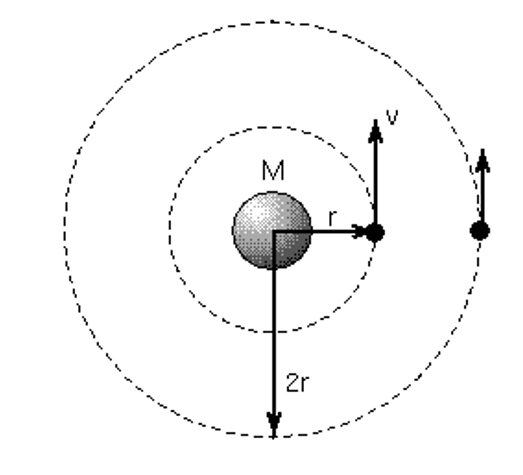

Sea M la masa de la Tierra y sea v la velocidad de un satelite (Luna) que orbita alrededor de la Tierra y, además, sea r el radio que va del centro de la Tierra al centro de la Luna (es decir, distancia de la superficie de la Tierra a la Luna más el radio de la Tierra), entonces sabemos lo siguiente:


$$M_T =\frac{{V_L }^2 r}{G}$$


Por lo tanto, si despejamos la velocidad de la Luna tenemos que:


$$V_L =\sqrt{\frac{GM_t }{r}}$$


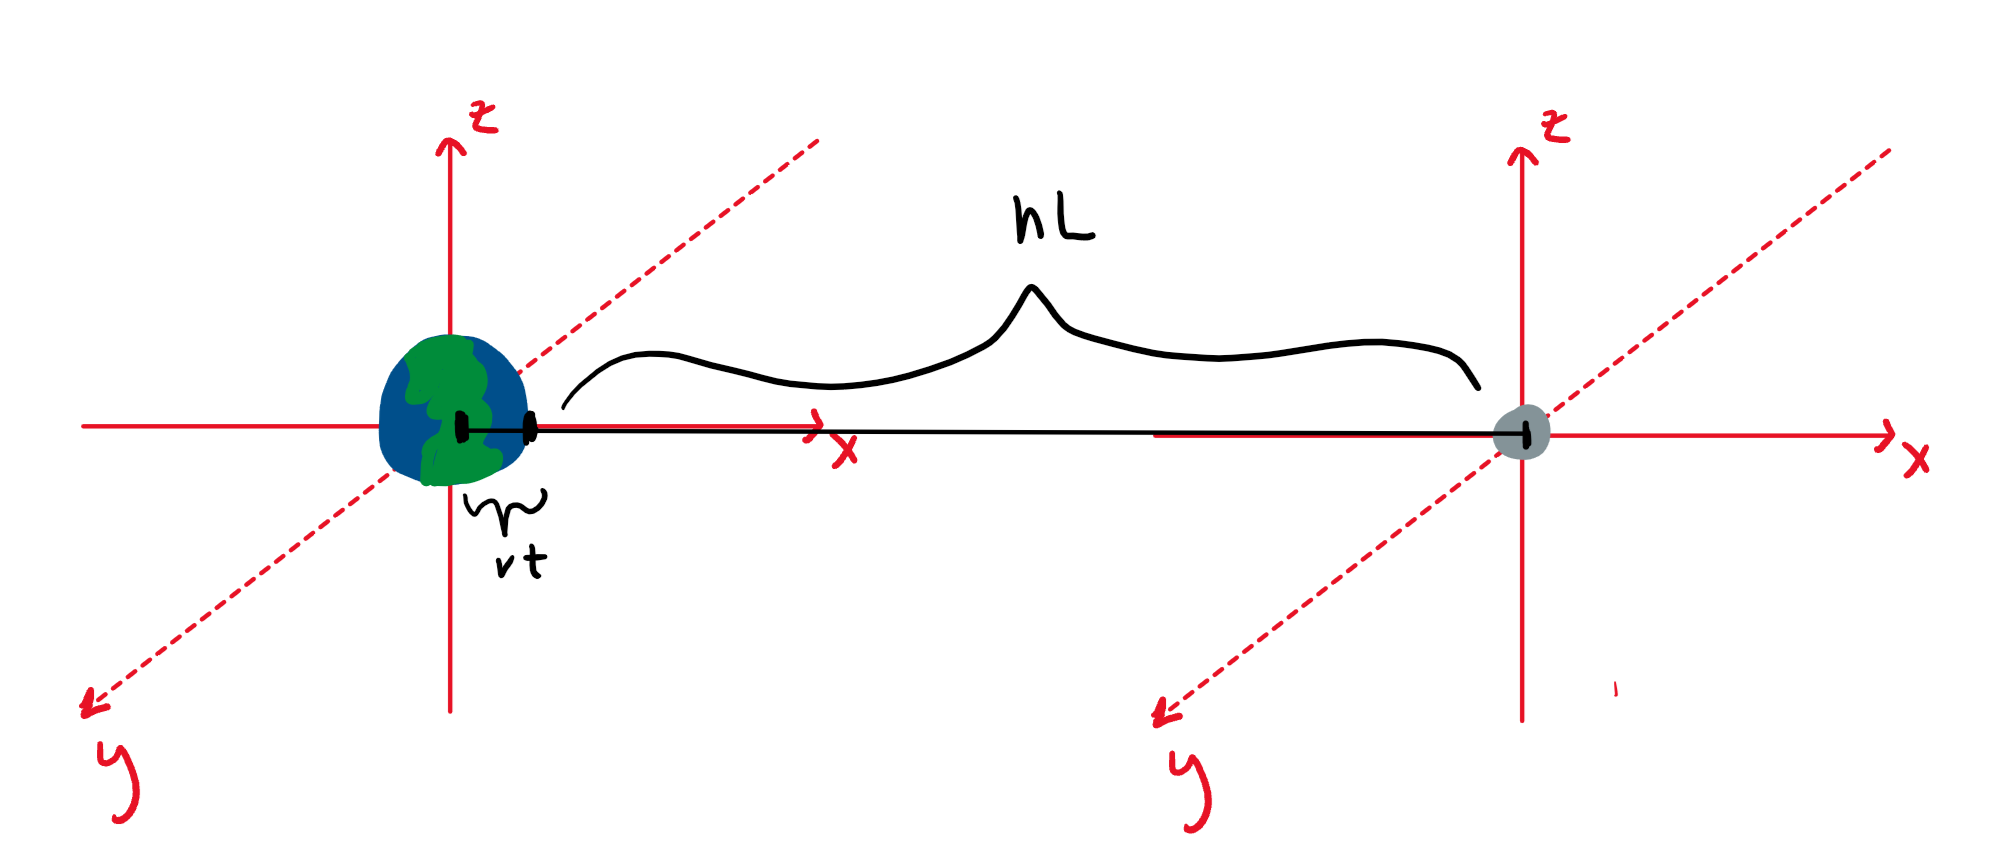


$$y=\left\lbrack \begin{array}{c}
r\\
v
\end{array}\right\rbrack$$



$$\mathrm{y'}=\left\lbrack \begin{array}{c}
v\\
a
\end{array}\right\rbrack$$


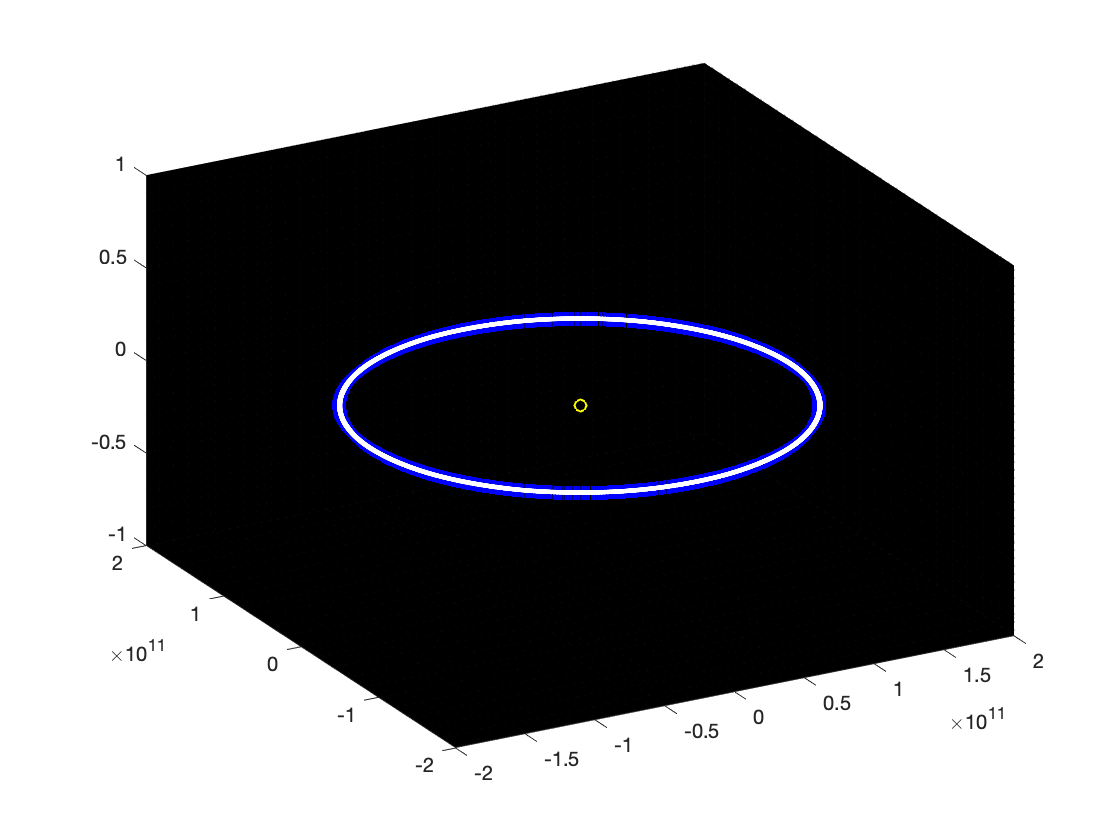

% Un satélite orbitando la Tierra
% La Tierra en el origen (inicialmente)
% El satélite tiene una masa de 20 toneladas 
% y se encuentra a 108 km de altura (eje x)
% Los vectores tienen los datos [Tierra, satélite]
  
% y  = [r;v] 
% y' = [v;a]
% dy/dt = f(t,y)

global G m;
G = 6.67408E-11;              % m3 kg-1 s-2
mS = 1.989e30;                % masa de Sol
mT = 5.9736e24;               % masa de Tierra
mL = 7.349e22;                % masa de la Luna
m = [mS, mT, mL]; 

rS = 695.510e6;               % radio del Sol m
rT = 6371e3;                        % radio de la Tierra m
hT = 149.6e9;                 % altura de la superficie del Sol a la Tierra
hL = 384400e3;                      % altura de la superficie de la Tierra a la Luna

r0 = [ [0;0;0], [rS+hT;0;0], [rS+hT+rT+hL;0;0] ];      
vT = sqrt(G * m(1)/r0(1,2));
vL1 = sqrt(G * m(1)/r0(1,3));  
vL2 = sqrt(G * m(2)/(rT+hL));  
v0 = [ [0;0;0], [0;vT;0], [0;vL1+vL2;0] ];         

wT = vT/(rS+hT);
wL = vL/(rS+rT+hL);
 
TT = (2*pi)/wT; 
TL = (2*pi)/wL; 

h = 60000;                 
nv = 10;                 
NkT = nv*ceil(TT/h); 
NkL = nv*ceil(TL/h);

pos = zeros(9,NkT+1);    
pos(:,1) = [r0(:,1);r0(:,2);r0(:,3)];

%Esto es un rk4 
y0 = [r0;v0];
%pos = ivps(@f1,0, NkT-1, y0, h,4)
pos = rk4(@f1, NkT, y1, pos, h);

hold on;
plot3(pos(1,:),pos(2,:),pos(3,:),'oy');
plot3(pos(4,:),pos(5,:),pos(6,:),'+b');
plot3(pos(7,:),pos(8,:),pos(9,:),'.w');
grid minor;
view([-29 32]);
set(gca,'Color','k')

function ydot = f1(~,y)
  global G m;                 
  r = y(1:3,:);
  v = y(4:6,:);
  
  drA = r(:,2) - r(:,1);         %Sol vs Tierra
  uA = drA / norm(drA);            
  drA2 = norm(drA)^2;         	 
  FA = (G*m(1)*m(2)/drA2) * uA;    
  
  drB = r(:,3) - r(:,1);         %Sol vs Luna
  uB= drB / norm(drB);            
  drB2 = norm(drB)^2;         	 
  FB = (G*m(1)*m(3)/drB2) * uB;    
  
  drC = r(:,3) - r(:,2);         %Luna vs Tierra
  uC= drC / norm(drC);            
  drC2 = norm(drC)^2;         	 
  FC = (G*m(2)*m(3)/drC2) * uC;    
  
  a = [(FA+FB)/m(1), -(FA-FC)/m(2), -(FB+FC)/m(3)];       %F = m.a
  
  ydot = [v;a];
end

function pos = rk4(f, Nk, y, pos, h)
    for t=2:Nk+1
      s1 = f(t,y);
      s2 = f(t+h/2,y+(h/2)*s1);
      s3 = f(t+h/2,y+(h/2)*s2);
      s4 = f(t+h, y+h*s3);
      slope = (s1+2*s2+2*s3+s4)/6;
      y = y + slope*h;
    
      r = y(1:3,:); 
      pos(:,t) = [r(:,1); r(:,2); r(:,3)];  
    end
end
